%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear all; close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Data
A = [-2,0;0,-1]; % dx = A*x

% Bidimensional Linear System
syms t x(t) y(t)

% Symbolic
dx = diff(x); dy = diff(y);
eqn = [dx;dy] == A*[x;y];
solg = dsolve(eqn)

solg = struct with fields:
    y: C2*exp(-t)
    x: C1*exp(-2*t)


t0 = 0

t0 = 0

% Sol 1:
xy0 = [1;1];
solp = dsolve(eqn,[x(t0);y(t0)]==xy0)

solp = struct with fields:
    y: exp(-t)
    x: exp(-2*t)


xp = solp.x; yp = solp.y;
xpts = double(subs(xp,t,linspace(0,3,100)));
ypts = double(subs(yp,t,linspace(0,3,100)));

figure;hold on
plot(xpts,ypts)
xlabel('x'); ylabel('y');
grid on;

% Sol 2:
xy0 = [-1;1];
solp = dsolve(eqn,[x(t0);y(t0)]==xy0)

solp = struct with fields:
    y: exp(-t)
    x: -exp(-2*t)


xp = solp.x; yp = solp.y;
xpts = double(subs(xp,t,linspace(0,3,100)));
ypts = double(subs(yp,t,linspace(0,3,100)));

plot(xpts,ypts)
xlabel('x'); ylabel('y');
grid on;

% Sol 3:
xy0 = [-1;-1];
solp = dsolve(eqn,[x(t0);y(t0)]==xy0)

solp = struct with fields:
    y: -exp(-t)
    x: -exp(-2*t)


xp = solp.x; yp = solp.y;
xpts = double(subs(xp,t,linspace(0,3,100)));
ypts = double(subs(yp,t,linspace(0,3,100)));

plot(xpts,ypts)
xlabel('x'); ylabel('y');
grid on;

% Sol 4:
xy0 = [1;-1];
solp = dsolve(eqn,[x(t0);y(t0)]==xy0)

solp = struct with fields:
    y: -exp(-t)
    x: exp(-2*t)


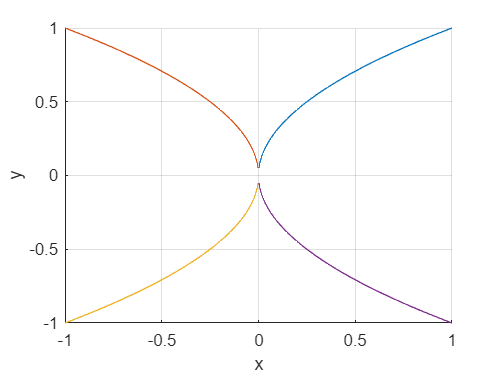

xp = solp.x; yp = solp.y;
xpts = double(subs(xp,t,linspace(0,3,100)));
ypts = double(subs(yp,t,linspace(0,3,100)));

plot(xpts,ypts)
xlabel('x'); ylabel('y');
grid on;